# Getting Started with BankfullMapper

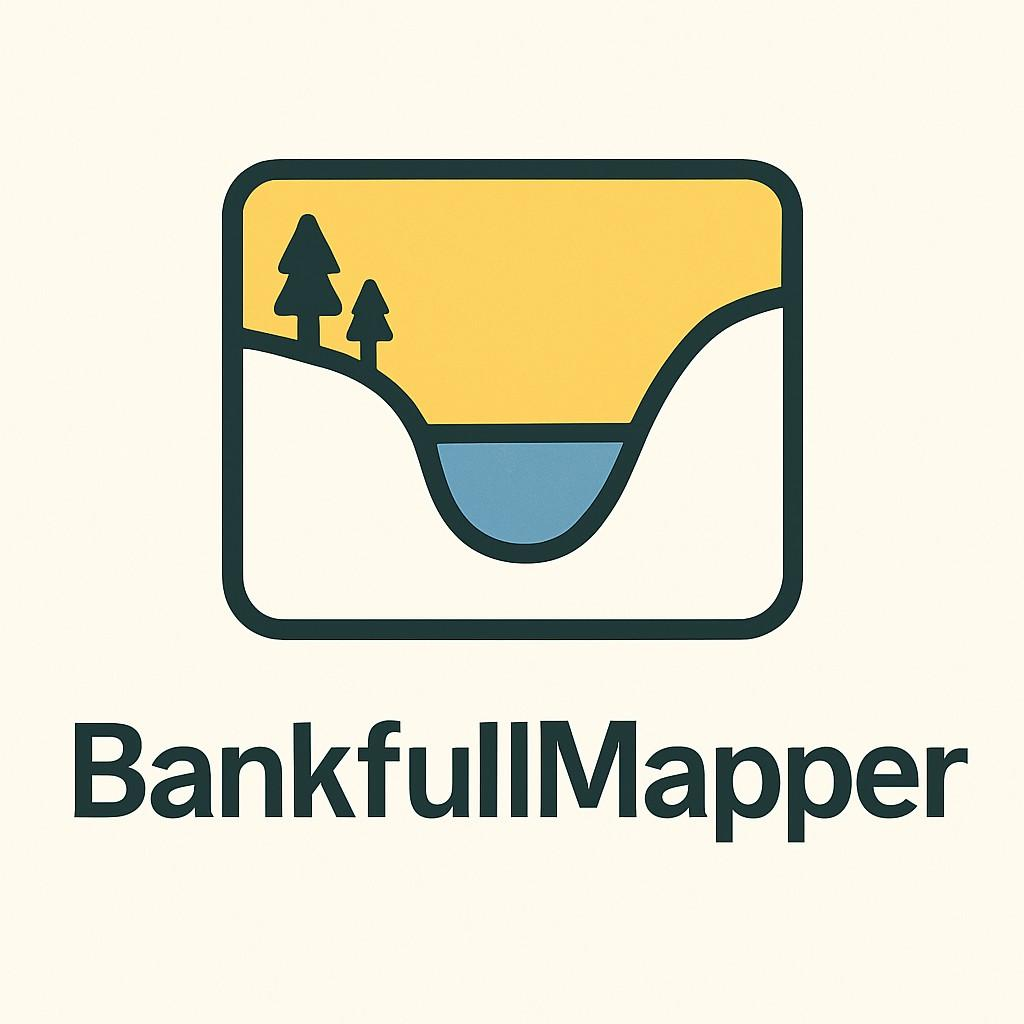

This toolbox provides a toolkit for bankfull geometry extraction and discharge estimation.

Contact to Michele Delchiaro (michele.delchiaro@uniroma1.it)

## System Requirements

This toolkit requires TopoToolbox, which can be downloaded from https://github.com/wschwanghart/topotoolbox, and needs the same Matlab's built-in packages required for runnning TopoToolbox.

## Features

This toolkit includes Matlab functions to analyze the river bankfull geometry and derive discharge estimate applying Manning's equation.  

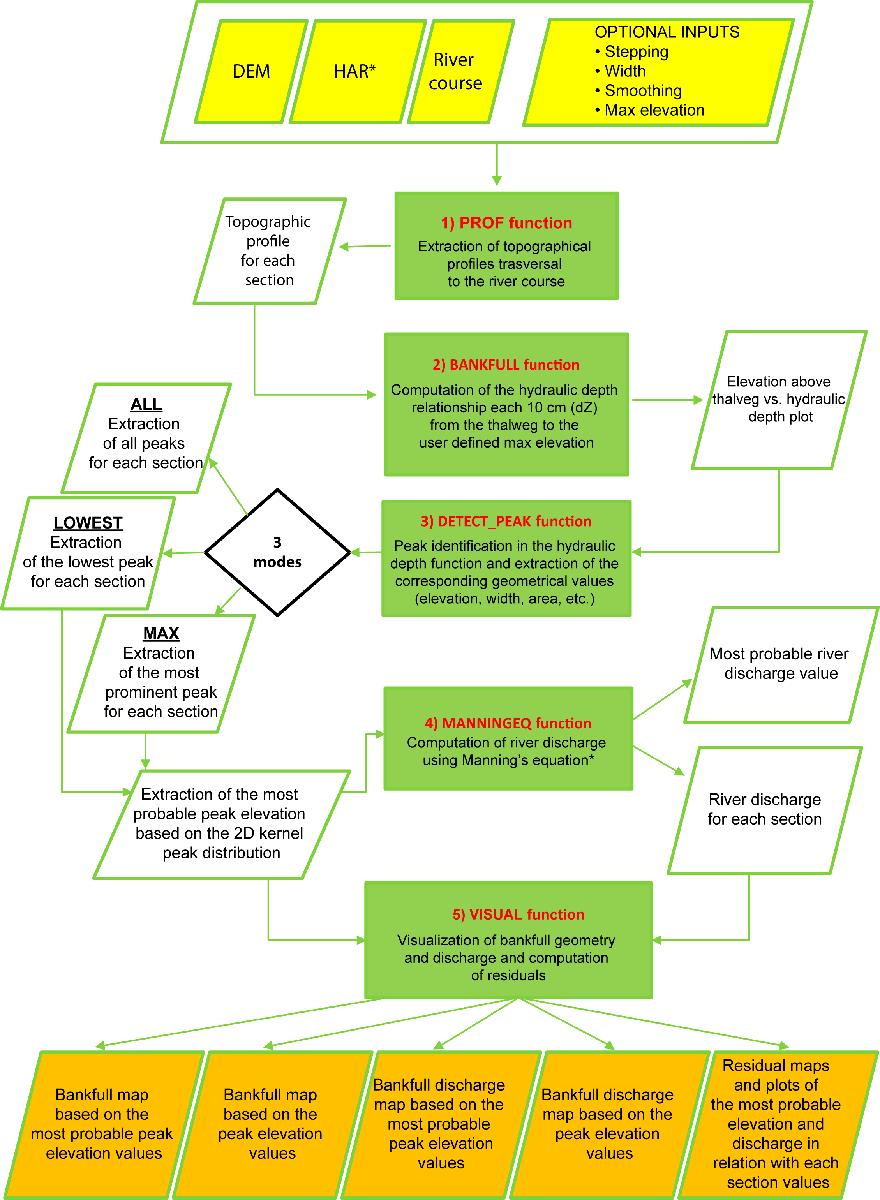

**HAR**: This function allows to compute the Relative Elevation Model (REM) or  Height Above River (HAR) model of a river

**PROF**: This function allows to extract profile from Relative Elevation Model (REM) or Height Above River (HAR) model as well as from Digital Elevation Model (DEM) 

**BANKFULL**: This function allows to extract flow height above thalveg vs. hydraulic depth values from the profiles obtained by the function PROF. For each profile, the hydraulic depth, defined as the ratio between the flow area and the flow width, is computed for different heights from the thalveg. In detail, the heigths range from 0 to max_depth every 10 cm.

**DETECT_PEAK**: This function allows to detect the peaks from the flow heigh above thalveg vs. hydraulic depth hydraulic depth curves of each profiles. It is possible to detect the all the peaks (using 'all' option), most prominent peaks (using 'max' option), and lowest peaks (using 'lowest' option). For the 'max' and 'lowest' option, the most probable Z value is also computed.

**SECTIONGRADIENT:** This function allows to compute the river gradient between the consecutive sections using a downstream elevation correction and a smoothing of the profile applying a moving mean with a user defined window size. Pay attention that the river course is supposed to go downstream.

**MANNINGEQ:** This function allows to compute the river discharge using the Manning's equation

**VISUAL: **This function allows to map the bankfull geometry and discharge based on the results obtained by DETECT_PEAK and MANNINGEQ functions. In detail, both peak elevation values and most probable values for each section are used for the bankfull geometry visualization. Regarding the discharge visualization, both the discharge computed with the peak elevation values and that with the most probable elevation Values are used. The bankfull elevation and discharge residuals are also computed by subtracting the most probable values with the peak values.

## Installation and Setup

You can either download the entire toolbox and add the folder `toolbox` and its subfolders to the search path. Alternatively, download the latest release of the toolbox (.mltbx). Once, you double-click the toolbox, it will be installed to MATLAB's add-on folder.

## **References**

Delchiaro, M., Ruscitto, V., Schwanghart, W., Brignone, E., Piacentini, D., and Troiani, F.. “BankfullMapper: a semi-automated MATLAB tool on high-resolution Digital Terrain Models for spatio-temporal monitoring of bankfull geometry and discharge”. Computers and Geosciences. [https://doi.org/10.1016/j.cageo.2025.106001](https://doi.org/10.1016/j.cageo.2025.106001)

Schwanghart, W., & Scherler, D., 2014. “TopoToolbox 2–MATLAB-based software for topographic analysis and modeling in Earth surface sciences”. Earth Surface Dynamics, 2(1), 1-7. [https://doi.org/10.5194/esurf-2-1-2014](https://doi.org/10.5194/esurf-2-1-2014)

## Getting Started

**DATA LOADING**

Load DEM

DEM=GRIDobj("test_data" + filesep + "dem_potenza.tif");

Load River Course

S=shaperead("test_data" + filesep + "potenza_river.shp");

% plot
figure
imageschs(DEM)
hold on
plot(S.X,S.Y,'w')

**REM COMPUTATION AND DEFINITION OF OPTIONAL INPUTS**

Compute REM using HAR function

REM=har(DEM,S);

% plot
figure
imageschs(DEM,REM)
hold on
plot(S.X,S.Y,'w')

Define optional inputs

% Optional inputs
step=50;        % stepping in meters between transversal river profiles
width=200;      % width in meters of the transversal river profiles
smooth=0;       % smoothing of the planar trace from which the profiles are extracted
max_depth=4;    % maximum height from the thalveg for which the bankfull is computed
n=0.05;         % n riverbed roughness coefficient in Manning's equation (Manning, 1904)

**EXTRACTION OF SECTION PROFILES**

Extract transverse river topographic profiles using PROF function

[d,z,z_dem,x,y,SW]=prof(DEM,REM,S,'step',step,'width',width,'smooth',smooth,'plot',true);

**HYDRAULIC DEPTH FUNCTION COMPUTATION**

Compute the hydraulic depth function for each profile using BANKFULL function

bank=bankfull(d,z,'max_depth',max_depth);

**BANKFULL PEAK EXTRACTION **

Extract peaks from the hydraulic depth function using DETECT_PEAK function

% ALL MODE: all the peaks are extracted
lim_all=detect_peak(bank.h,bank.area,bank.width,bank.elevation,'peak','all');
% LOWEST MODE: the lowest peaks are extracted
lim_low=detect_peak(bank.h,bank.area,bank.width,bank.elevation,d,z,'peak','lowest');
% MAX MODE: the most prominent peaks are extracted
lim_max=detect_peak(bank.h,bank.area,bank.width,bank.elevation,d,z,'peak','max');

**RIVER SLOPE COMPUTATION**

Compute river slope using SECTIONGRADIENT function

ws=10;          % cell windowsize for moving average computation on slope smoothing 
[slope,~,~,~]=sectiongradient(DEM,SW,step,'windowsize',ws);

**DISCHARGE ESTIMATION**

Compute Manning's Equation using MANNINGEQ function

%% MANNING'S EQUATION COMPUTATION (for lowest and max mode extracted peaks)
% discharge computation using the measured peak elevation 
R_low=manningseq(SW,z,z_dem,step,d,lim_low.zlim,'n',n,'slope',slope);
R_max=manningseq(SW,z,z_dem,step,d,lim_max.zlim,'n',n,'slope',slope);

% discharge computation using the most probable elevation 
R_low2=manningseq(SW,z,z_dem,step,d,lim_low.zvar,'n',n,'slope',slope);
R_max2=manningseq(SW,z,z_dem,step,d,lim_max.zvar,'n',n,'slope',slope);

**BANKFULL MAPPING**

Map Bankfull geometry and discharge using VISUAL function 

% for lowest mode extracted peaks
[f_Zlim_low,f_Zvar_low,f_Qlim_low,f_Qvar_low,residual_Z_low,residual_Q_low,res_Z_low,res_Q_low]=visual(REM,DEM,SW,step,lim_low.zlim,lim_low.zvar,R_low.Q_zvar,R_low2.Q_zvar,'plot',true);
% for max mode extracted peaks
[f_Zlim_max,f_Zvar_max,f_Qlim_max,f_Qvar_max,residual_Z_max,residual_Q_max,res_Z_max,res_Q_max]=visual(REM,DEM,SW,step,lim_max.zlim,lim_max.zvar,R_max.Q_zvar,R_max2.Q_zvar,'plot',true);
